# Feature Ranking Algorithms

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and displays the data.

rng(0)
T = readtable("./data/pumpFeatures.csv")

T = 1000×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean    

This code fits a 5-fold cross-validated classification tree model to the original data, calculates the loss, and displays a confusion chart.

mdlFull = fitctree(T, "faultCode", "KFold", 5);
fullLoss = kfoldLoss(mdlFull)

fullLoss = 0.1360

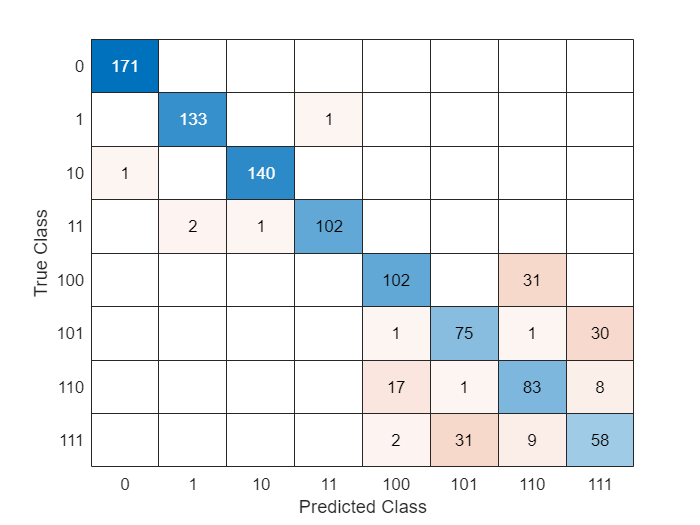

confusionchart(T.faultCode, kfoldPredict(mdlFull))

## Tasks 1 & 5

You can use the function `fschi2` to rank the predictor variables according to the Chi-Square algorithm.

`[``idx``,``scores``]` `=` `fscchi2``(``tbl``,``"``Response``"``)`

How did the model perform using these predictors? Different algorithms might select different predictors. You can try different feature ranking algorithms to decide which predictors to keep.

[idx, scores] = fscmrmr(T, "faultCode");

## Task 2

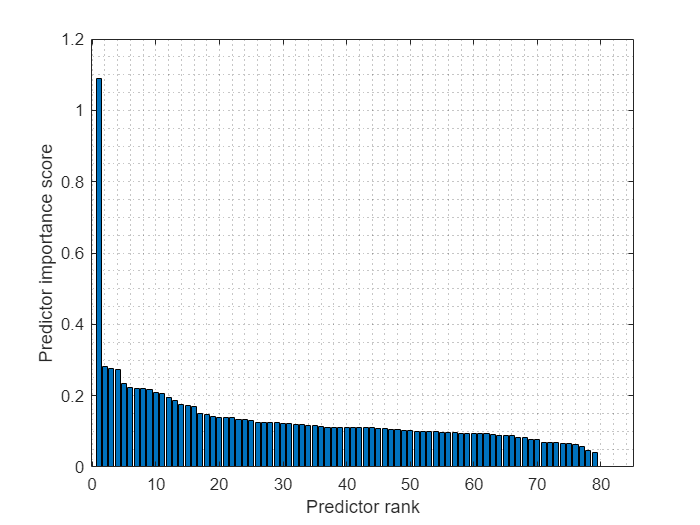

bar(scores(idx))
grid minor
xlabel("Predictor rank")
ylabel("Predictor importance score")

## Task 3

You can use logical indexing to select a subset of predictors according to their importance. Remember, `idx(1)` contains the most important predictor.

toKeep = idx(1:15);
selected = T(:, [toKeep, end]);

## Task 4

After selecting the predictors to use, you can fit a model to this subset and see how those affect the model performance

mdlPart = fitctree(selected, "faultCode", "KFold", 5);
partLoss = kfoldLoss(mdlPart)

partLoss = 0.1160

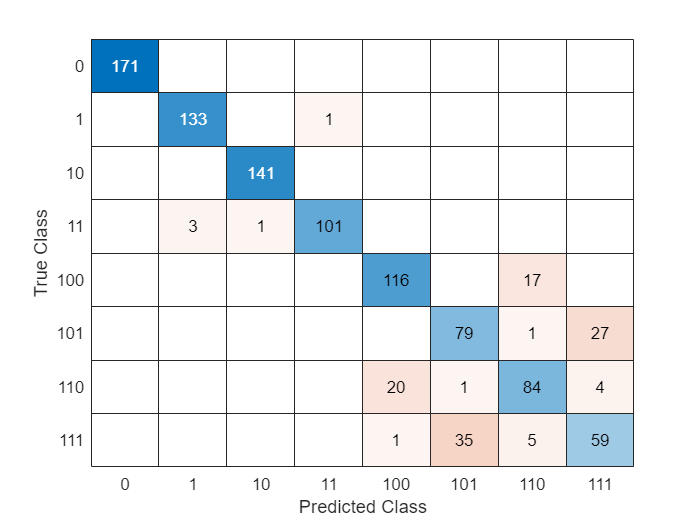

confusionchart(T.faultCode, kfoldPredict(mdlPart))